## Estimate model from square wave, validate with sine wave

Hyperparams

clear
trainingFile = "tower_crane_sine_test_data.mat";
validationFile = "tower_crane_square_test_data.mat";
output = "pendulum";

trainingStruct = load(trainingFile);
validationStruct = load(validationFile);

% sampling time
Ts = 0.002;

Preprocessing: cut off a few seconds

secondsToCutOff =0;
% like this because matlab passes by value
trainingStruct = cutoffBeginning(trainingStruct, Ts, secondsToCutOff);
validationStruct = cutoffBeginning(validationStruct, Ts, secondsToCutOff);
% set options appropriately
tfestOpt = tfestOptions;
ssestOpt = ssestOptions;
initialCondZero = false;
if secondsToCutOff == 0
  initialCondZero = true;
  tfestOpt.InitialCondition = 'zero';
  ssestOpt.InitialState = 'zero';  
end

load training and validation data

[t, y, u] = extract(trainingStruct, output);
[t_val, y_val, u_val] = extract(validationStruct, output);

constants

N = length(t);
% why this line?
t = (0:Ts:(N-1)*Ts)';

Create data and estimate transfer function

numberPoles = 3

numberPoles = 3

data = iddata(y, u, Ts);
data_val = iddata(y_val, u_val, Ts);

%Gest = tfest(data, 3, 1, 0, opt)
% only specify number of poles
Gest = tfest(data, numberPoles, tfestOpt)

Gest =
 
  From input "u1" to output "y1":
   0.9218 s^2 - 36.29 s + 33.84
  -------------------------------
  s^3 + 3.378 s^2 + 227 s + 438.5
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 92.34%                   
FPE: 0.0001036, MSE: 0.0001034                   


See fit on training data

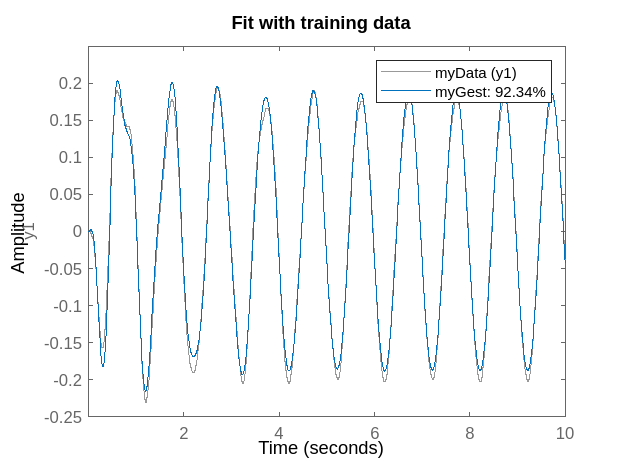

myCompare(data, Gest, initialCondZero)
title('Fit with training data')

See fit on validation data

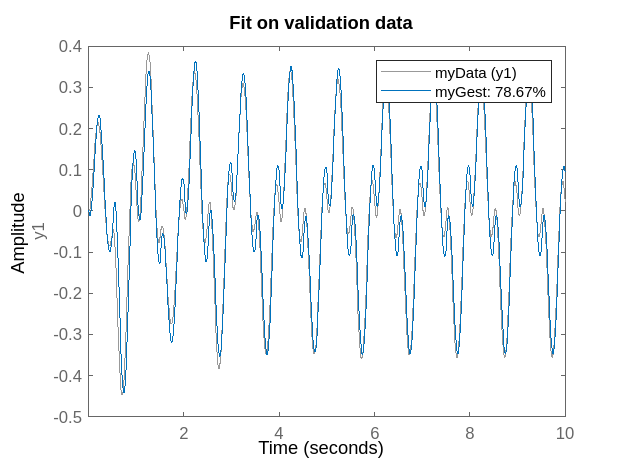

myCompare(data_val, Gest, initialCondZero)
title('Fit on validation data')

Estimate model with ssest

% telling initial state is zero in the options
Gss = ssest(data, 1:10, ssestOpt);
Gest_new = tf(Gss)

Gest_new =
 
  From input "u1" to output "y1":
    -1.197 s - 15.74
  ---------------------
  s^2 + 2.915 s + 131.7
 
Continuous-time transfer function.



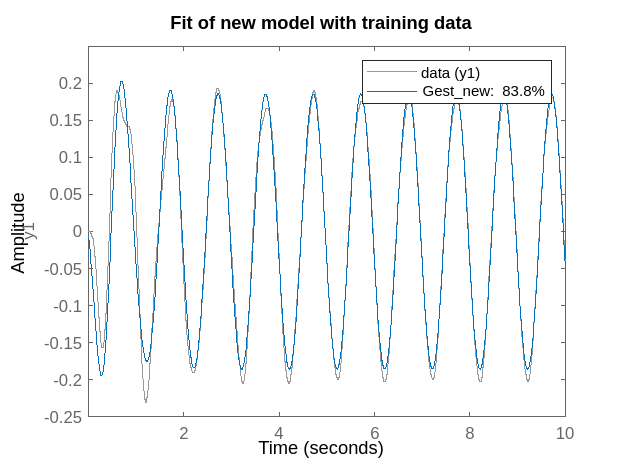

compare(data, Gest_new)
title('Fit of new model with training data')

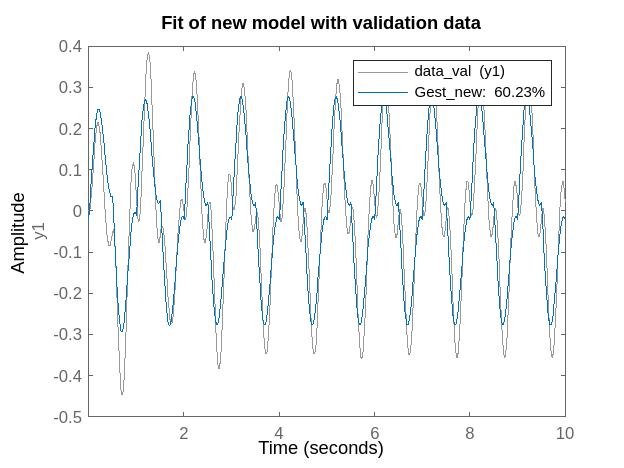

compare(data_val, Gest_new)
title('Fit of new model with validation data')

if we cut something off for training, compare the obtained model with the entire data

if not(initialCondZero) 
    skipSec = 0
    [t_c, y_c, u_c] = extractComplete(trainingStruct, output, Ts, skipSec);
    [t_c_val, y_c_val, u_c_val] = extractComplete(validationStruct, output, Ts, skipSec);
    % TODO modular if arm or pendulum
    data_c = iddata(y_c, u_c, Ts);
    data_c_val = iddata(y_c_val, u_c_val, Ts);
    figure
    myCompare(data_c, Gest_new, skipSec == 0)
    title('Fit of model trained with cutoff data with the complete data')
    
    figure
    myCompare(data_c_val, Gest_new, skipSec == 0)
    title('Fit of model trained with cutoff data with the complete data (validation)')
end

Sanity check : system response to constant zero input

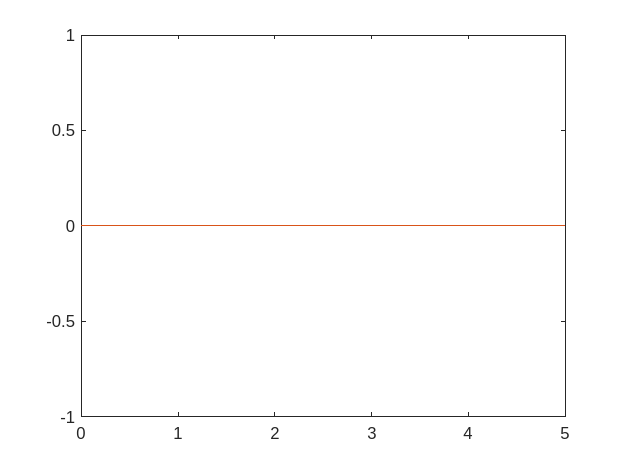

time = 0:Ts:5;
zero_input = zeros(length(time), 1);
zero_response = lsim(Gest, zero_input, time);
zero_response_new = lsim(Gest_new, zero_input, time);

plot(time, [zero_input, zero_response])

plot(time, [zero_input, zero_response_new])

helper function

function [t, y, u] = extract(dataStruct, output)
    data_crane = dataStruct.data_crane;
    t = data_crane(1,:)';
    % default index arm = 2
    index_y = 2;
    if output == "pendulum"
        index_y = 3;
    end
    y = data_crane(index_y,:)';
    u = data_crane(4,:)';
end

% extract complete data in case the normal data is cut off
function [t, y, u] = extractComplete(dataStruct, output, Ts, skipSec)
    startIndex = (skipSec / Ts) + 1; 
    data_crane = dataStruct.data_crane_complete;
    t = data_crane(1, startIndex:end)';
    index_y = 2;
    if output == "pendulum"
        index_y = 3;
    end
    y = data_crane(index_y, startIndex:end)';
    u = data_crane(4, startIndex:end)';
end

Compare with initial conditions as potentially zero

function myCompare(myData, myGest, initialCondZero)
    opt = compareOptions;
    if initialCondZero
        opt.InitialCondition = 'zero';
    end
    compare(myData, myGest, opt);  
end

cutoff transitory response

function result = cutoffBeginning(dataStruct, Ts, secondsToCutOff)
    if secondsToCutOff > 0
    dataStruct.data_crane_complete = dataStruct.data_crane;
    dataStruct.data_crane = dataStruct.data_crane(1:end, round(secondsToCutOff / Ts) + 1 : end);
    end
    result = dataStruct;
end